# Experiment 1

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

## Part1: stem and plot functions

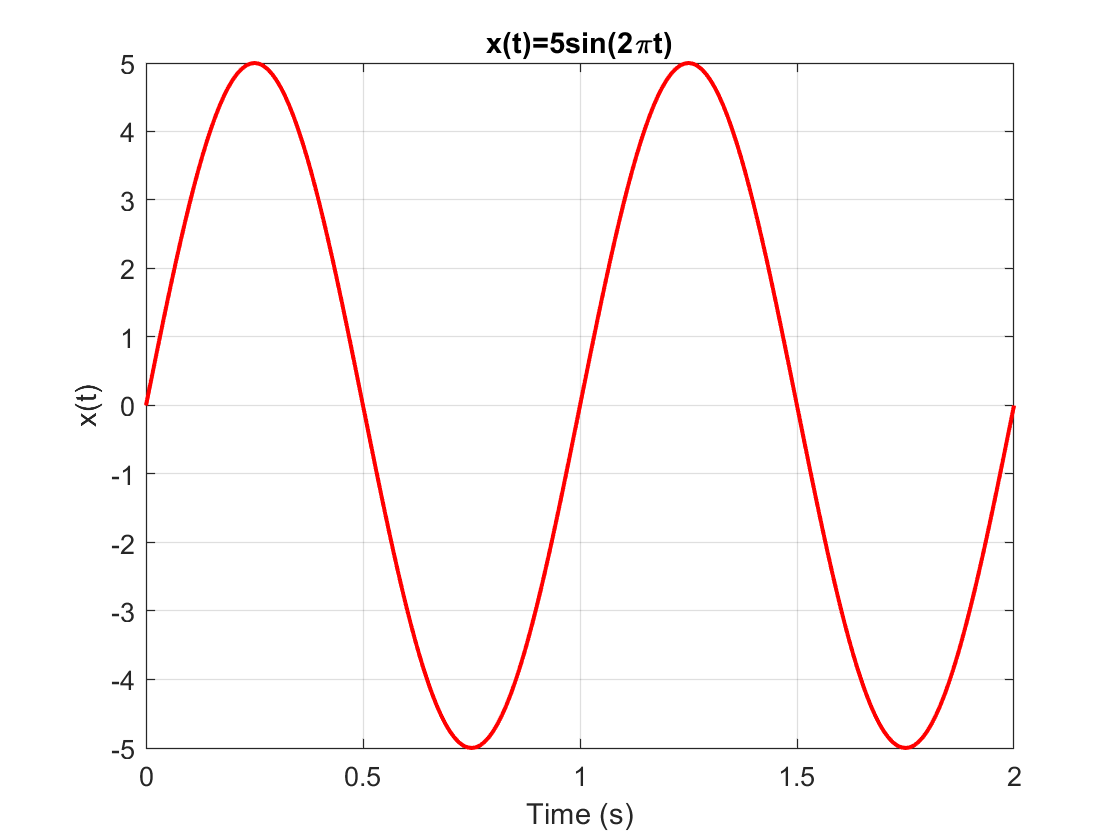

Ts = 0.01;
t = 0:Ts:2;
N = length(t);
x = 5*sin(2*pi*t);
figure("Name","sine function using plot");
plot(t, x, LineWidth=1.5, Color='r');
grid on;
title('x(t)=5sin(2\pit)');
xlabel('Time (s)');
ylabel('x(t)');

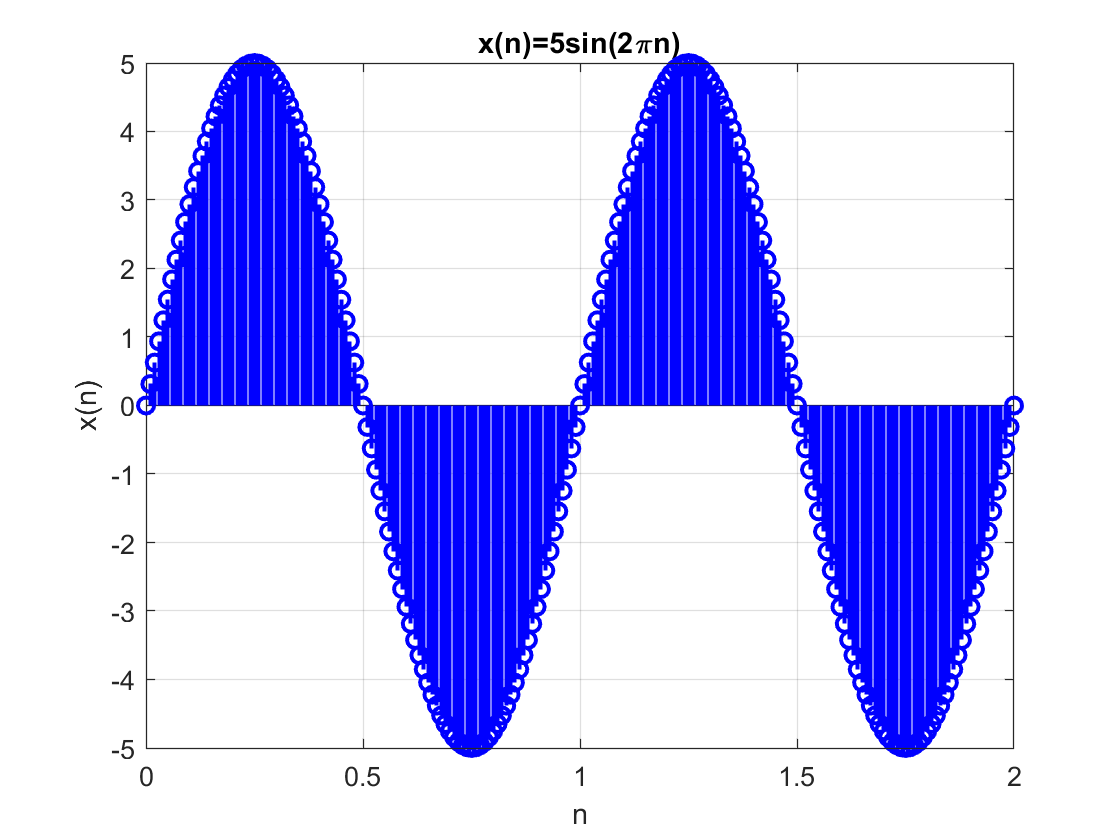

figure("Name","sine function using stem");
stem(t, x, LineWidth=1.5, Color='b');
grid on;
title('x(n)=5sin(2\pin)');
xlabel('n');
ylabel('x(n)');

## Part2: subplot

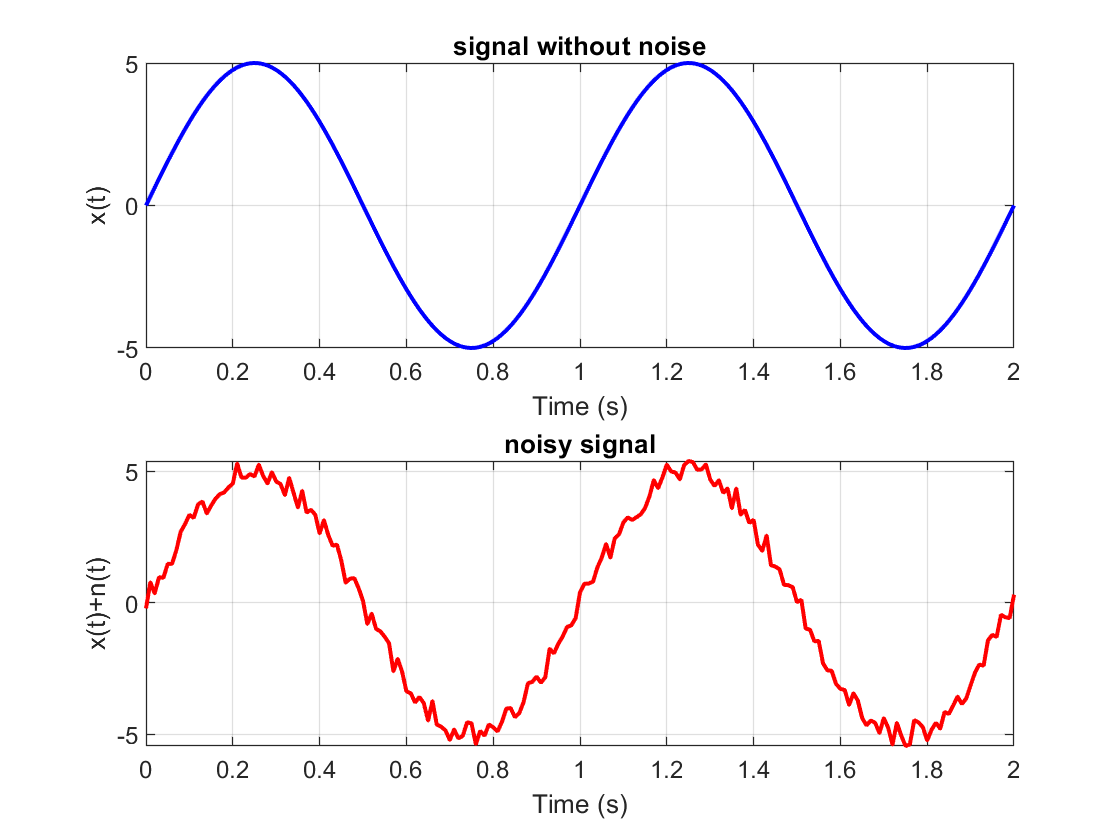

noise = rand(1,N)-0.5; % uniform between -0.5 and 0.5
noisy_x = x + noise;
figure("Name","plot x and noisy_x plot");
subplot(2,1,1);
plot(t,x, 'b', 'LineWidth', 1.5);
grid on;
title('signal without noise');
xlabel('Time (s)');
ylabel('x(t)');
subplot(2,1,2);
plot(t,noisy_x,  'r', 'LineWidth', 1.5);
grid on;
title('noisy signal');
xlabel('Time (s)');
ylabel('x(t)+n(t)');

## Part3: conv function

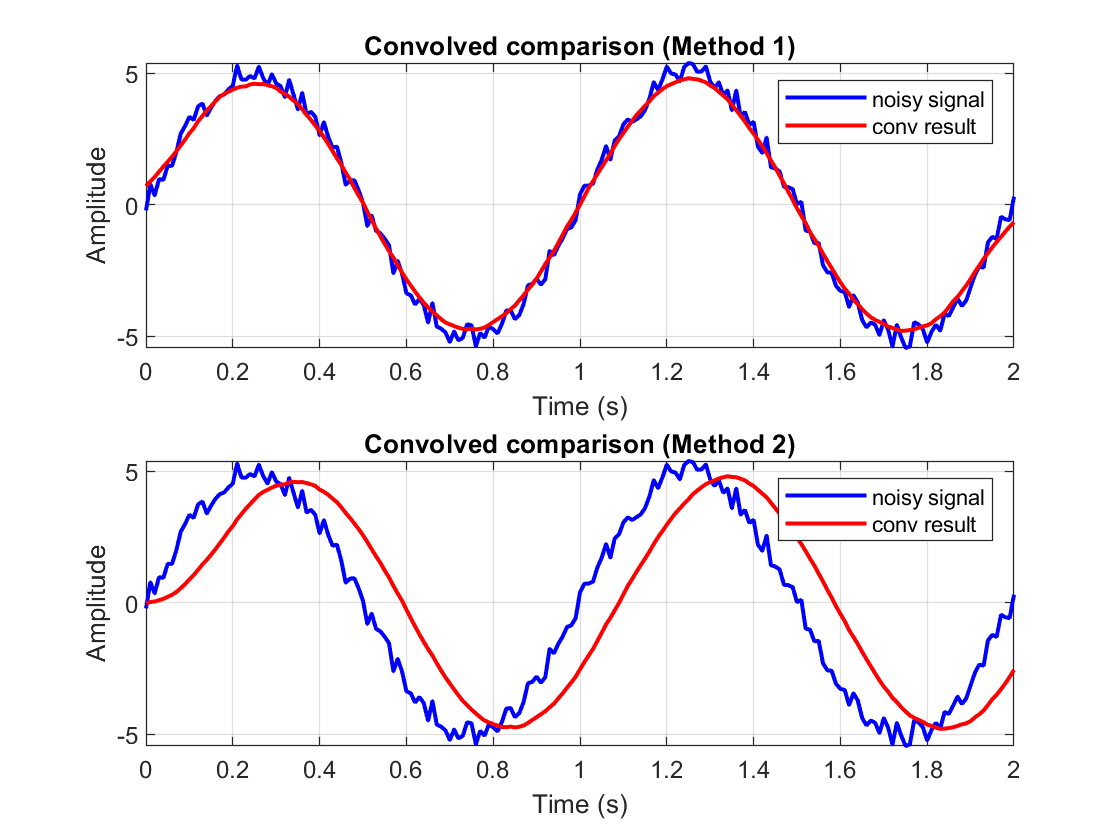

M1 = 0; 
M2 = 20;
filter_length = M2 + M1 - 1;  
moving_avg = ones(1, filter_length) / filter_length;  

conv_result1 = conv(noisy_x, moving_avg, 'same');  
figure("Name","convolution");
subplot(2,1,1);
plot(t, noisy_x, 'b', 'LineWidth', 1.5);
hold on;
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

plot(t, conv_result1, 'r', 'LineWidth', 1.5);
title('Convolved comparison (Method 1)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('noisy signal','conv result');
hold off;

conv_result2 = conv(noisy_x, moving_avg);  
conv_result2 = conv_result2(1:length(noisy_x));
subplot(2,1,2);
plot(t, noisy_x, 'b', 'LineWidth', 1.5);
hold on;
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

plot(t, conv_result2, 'r', 'LineWidth', 1.5);
title('Convolved comparison (Method 2)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('noisy signal','conv result');
hold off;

The group delay of a moving average signal with M1=0 and M2=20 is 10. So the signal has a delay of 10 samples.

As we can see in 'method 1' when we use 'same' in our conv function it will take some points in the middle so we don't have the delay.

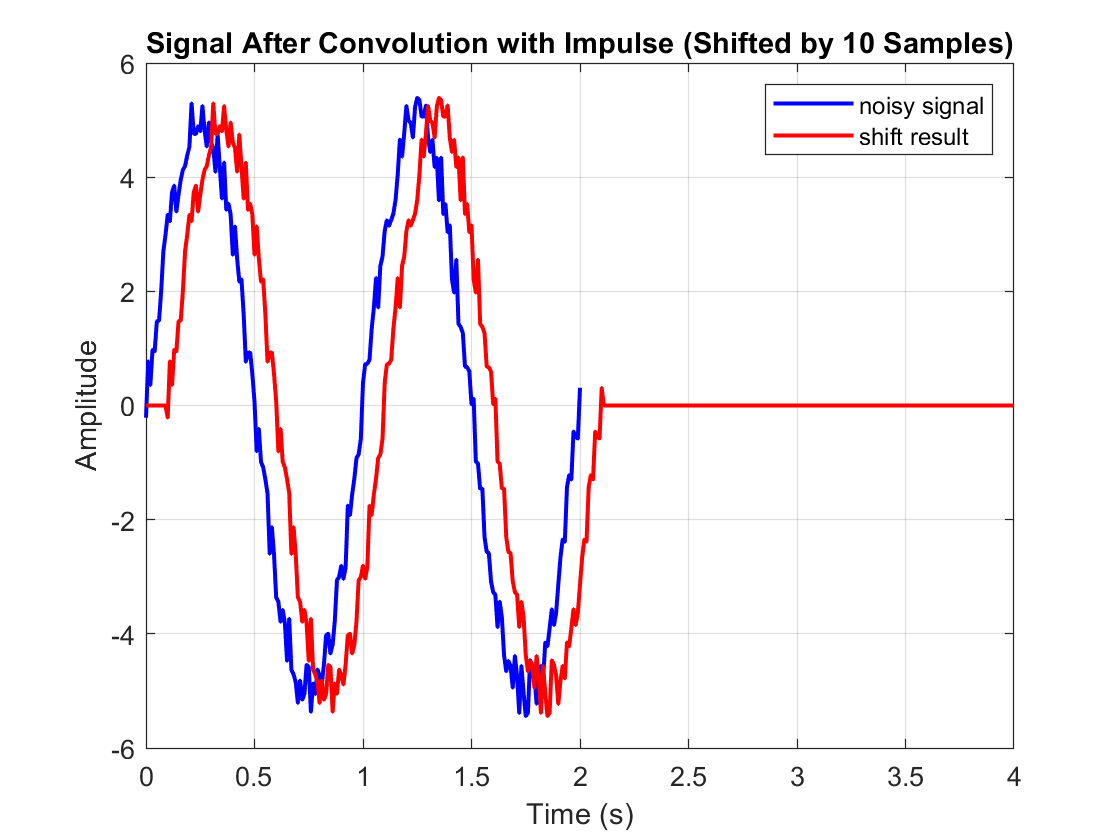

h_shift = zeros(1, N);  
h_shift(11) = 1;  
t_conv = 0:0.01:4;
shifted_signal = conv(noisy_x, h_shift); 

figure("Name","shifting convolution");
plot(t, noisy_x, 'b', 'LineWidth', 1.5);
hold on;
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

plot(t_conv, shifted_signal, 'r', 'LineWidth', 1.5);
title('Signal After Convolution with Impulse (Shifted by 10 Samples)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('noisy signal','shift result');
hold off;

## Part4: filter function

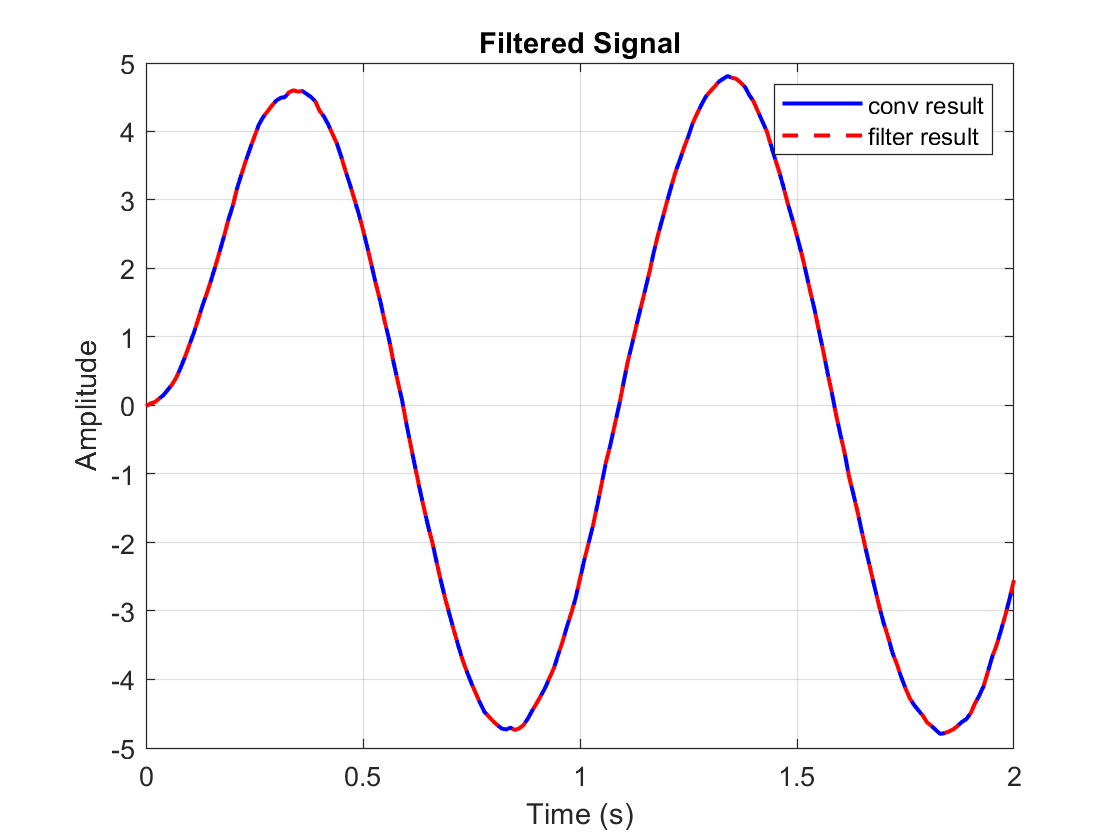

filtered_signal = filter(moving_avg,1,noisy_x);
figure("Name","using filter function");
plot(t, conv_result2, 'b', 'LineWidth', 1.5);
hold on;
title('Convolved comparison (Method 2)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

plot(t, filtered_signal, 'r--', 'LineWidth', 1.5);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('conv result','filter result');
hold off;

As we can see in the figure using filter function is the same as method 2 in using conv function.

## Part 5: function definition

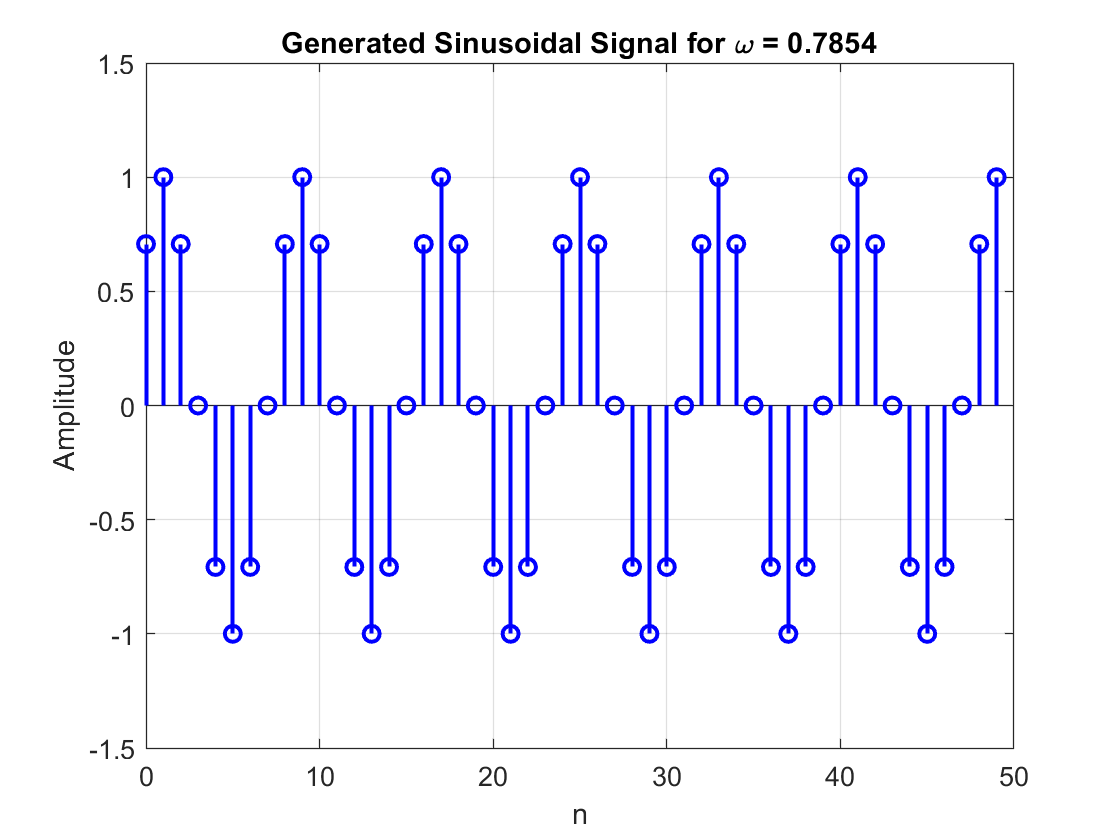

n = 50;  
omega = pi/4;  
x = singen(omega, n);

stem(0:n-1, x, 'b', 'LineWidth', 1.5);
ylim([-1.5,1.5]);
xlabel('n'); ylabel('Amplitude');
title(['Generated Sinusoidal Signal for \omega = ', num2str(omega)]);
grid on;

function x = singen(omega, n)
    b = [sin(omega), 0];  
    a = [1, -2*cos(omega), 1];  

    delta = [1, zeros(1, n-1)];  

    x = filter(b, a, delta);
end